clearvars, clc;

wavelength = (1530 : 0.1 : 1594-0.1) .* 1e-9; % nm
c = 299792458;
t = (0 : 0.1 : 100-0.1) .* 1e-9; % ns
[B, H] = JonesMatrix(wavelength, t);
N = length(B);

T = zeros(2*length(t), 2*length(wavelength));
for tindex = 1 : length(t)
    for windex = 1 : length(wavelength)
        % 计算填充的T
        Ttemp= H{N+1}(:, 2*tindex-1: 2*tindex);
        for i = N : -1 : 1
            Ttemp = Ttemp * B{i}(:, 2*windex-1: 2*windex);
            Ttemp = Ttemp * H{i}(:, 2*tindex-1: 2*tindex);
        end
        T(2*tindex-1: 2*tindex, 2*windex-1: 2*windex) = Ttemp;
    end
end

Q = zeros(length(T), width(T)-2);
vec_tau = zeros(3, 1);
FOPMD = zeros(length(T)/2, width(T)/2-1);
for tindex = 1 : (length(T)/2)
    for windex = 1 : (width(T)/2 - 1)
        df = c./wavelength(windex) - c./wavelength(windex+1);
        dw = 2*pi*df;
        dT = T(2*tindex-1: 2*tindex, 2*windex+1: 2*windex+2) - T(2*tindex-1: 2*tindex, 2*windex-1: 2*windex);
        dT = dT ./ dw;
        Q(2*tindex-1: 2*tindex, 2*windex-1: 2*windex) = 1j * dT * T(2*tindex-1: 2*tindex, 2*windex-1: 2*windex);
        vec_tau(1) = Q(2*tindex-1, 2*windex-1) - Q(2*tindex, 2*windex);
        vec_tau(2) = Q(2*tindex-1, 2*windex) + Q(2*tindex, 2*windex-1);
        vec_tau(3) = 1j * (Q(2*tindex, 2*windex-1) - Q(2*tindex-1, 2*windex));
        FOPMD(tindex, windex) = norm(vec_tau, 2);
    end
end

Q = zeros(length(T), width(T)-2);
vec_tau = cell(3, 1);
vec_tau{1} = zeros(length(t), length(wavelength)-1);
vec_tau{2} = zeros(length(t), length(wavelength)-1);
vec_tau{3} = zeros(length(t), length(wavelength)-1);
FOPMD = zeros(length(T)/2, width(T)/2-1);
for tindex = 1 : (length(T)/2)
    for windex = 1 : (width(T)/2 - 1)
        df = c./wavelength(windex) - c./wavelength(windex+1);
        dw = 2*pi*df;
        dT = T(2*tindex-1: 2*tindex, 2*windex+1: 2*windex+2) - T(2*tindex-1: 2*tindex, 2*windex-1: 2*windex);
        dT = dT ./ dw;
        Q(2*tindex-1: 2*tindex, 2*windex-1: 2*windex) = 1j * dT * T(2*tindex-1: 2*tindex, 2*windex-1: 2*windex);
        vec_tau{1}(tindex, windex) = Q(2*tindex-1, 2*windex-1) - Q(2*tindex, 2*windex);
        vec_tau{2}(tindex, windex) = Q(2*tindex-1, 2*windex) + Q(2*tindex, 2*windex-1);
        vec_tau{3}(tindex, windex) = 1j * (Q(2*tindex, 2*windex-1) - Q(2*tindex-1, 2*windex));
        temp = [vec_tau{1}(tindex, windex), vec_tau{2}(tindex, windex), vec_tau{3}(tindex, windex)];
        FOPMD(tindex, windex) = norm(temp, 2);
    end
end

SOPMD = zeros(length(FOPMD), width(FOPMD)-1);
dvec_tau = zeros(3, 1000);
for i = 1 : width(SOPMD)
    df = c./wavelength(i) - c./wavelength(i+1);
    dw = 2*pi*df;
    dvec_tau(1, :) = (vec_tau{1}(:, i+1) - vec_tau{1}(:, i)) ./ dw;
    dvec_tau(2, :) = (vec_tau{2}(:, i+1) - vec_tau{2}(:, i)) ./ dw;
    dvec_tau(3, :) = (vec_tau{3}(:, i+1) - vec_tau{3}(:, i)) ./ dw;
    for tindex = 1 : length(SOPMD)
        SOPMD(tindex, i) = norm(dvec_tau(:, tindex), 2);
    end
end

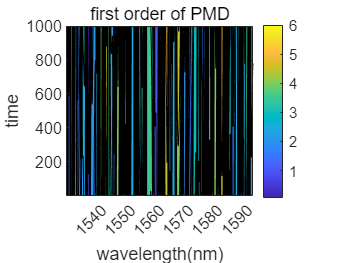

FOPMD = FOPMD .* 1e12; % ps
figure
contourf(FOPMD); %ps
LevelList = [6, 5, 4, 3, 2, 1];
colorbar
set(gca, 'XTick', 100 : 100: 900, 'XTickLabel', [1540, 1550, 1560, 1570, 1580, 1590]);
xlabel('wavelength(nm)')
ylabel('time')
title('first order of PMD')

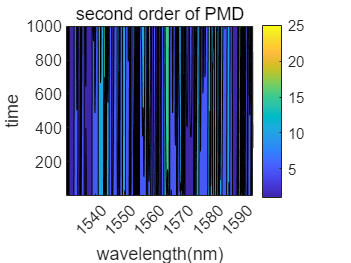

SOPMD = SOPMD .* 1e24; % ps^2
figure
contourf(SOPMD); %ps
LevelList = [6, 5, 4, 3, 2, 1];
colorbar
set(gca, 'XTick', 100 : 100: 900, 'XTickLabel', [1540, 1550, 1560, 1570, 1580, 1590]);
xlabel('wavelength(nm)')
ylabel('time')
title('second order of PMD')